# 4.1 Padé approximation

Alexandre Rey, MSE, Ma-StatDig, 2022

clear;
rng default;
addpath('../functions/');

Méthode très simple qui fonctionne sur quelques échantillons en début de signal. Avec le ARMA(1,1) ça fonctionne bien mais uniquement tant que le signal n'est pas bruité, en rajoutant du bruit Padé ne fonctionne plus.

Padé $\approx$ régression sur les $n$ premiers échantillons

## Example 4.3.2

Test padé approximation with the signal $x(n)$ defined below: $x(n) = \begin{cases}
1 & \text{si n=0}\\
3\cdot 0.5^{n} & \text{sinon}
\end{cases}$ 

Test with AR(2) model, AM(2) and ARMA(1,1).

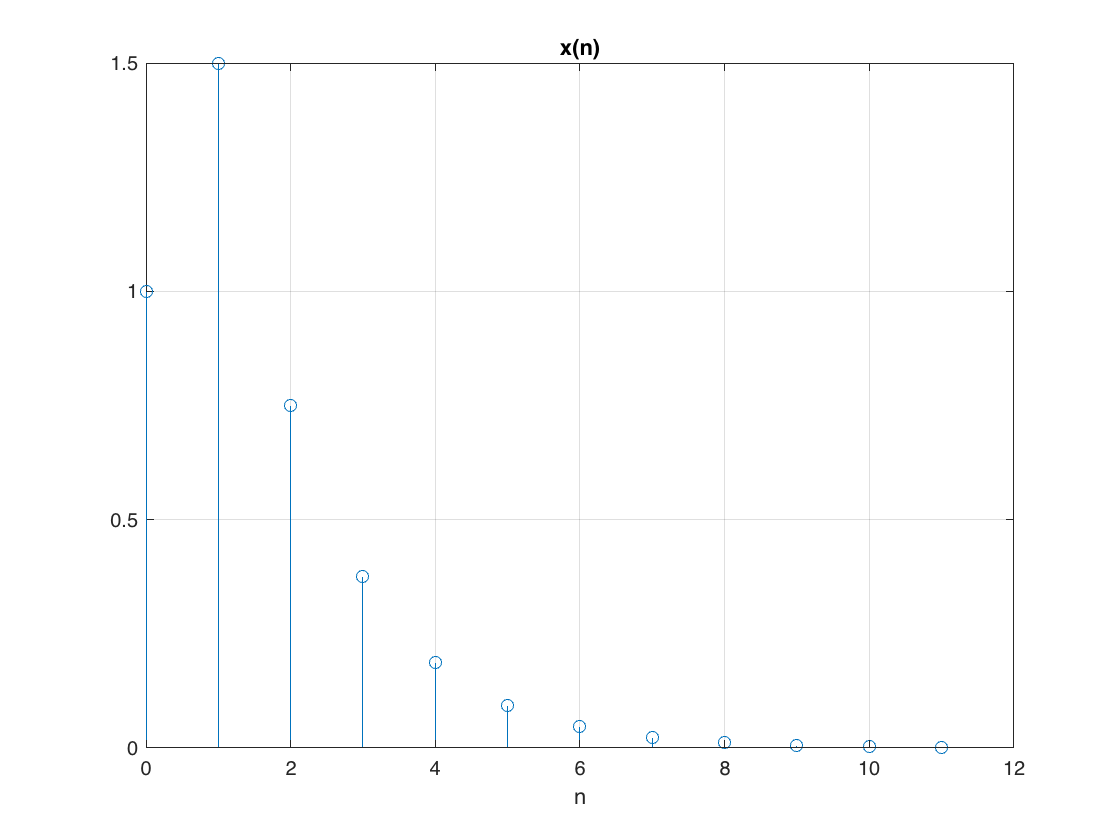

N = 12;
n = 0:N-1;
xn = [1, 3*(0.5).^n(2:end)];                % noiseless signal
An = 0.2;       % noise amplitude
%xn = [1, 3* (0.5).^n(2:end)]+ An*randn(1,N) % noisy signal
xn = xn(:);
dn = [1, zeros(1,N-1)];                     % unit sample

figure;
    stem(n,xn);
    title('x(n)');
    xlabel('n');
    grid;

### a) Test with AR(2): p=2, q=0


$$H(z) = \frac{b(0)}{1+a(1)z^{-1}+a(2)z^{-2}}$$
 

Compute the $X_q$ matrix using the Matlab `convmtx() `function and chose the right index to extract the $X_q$ as in theory eq (4.13)

p= 2;
q = 0;
X = convmtx(xn, p+1);   % /!\ +1 due to matlab indexes [1..n]
Xq = X(q+2:q+p+1, 2:p+1)

Xq =     1.0000         0
    1.5000    1.0000


Compute the vector $x_{q+1}$ as well:

xq_1 = X(q+2:q+p+1, 1)

xq_1 =     1.5000
    0.7500


And now compute the $a_p$ coefficients:

if det(Xq) % Xq is non singular
  % ap_ar = inv(Xq)*(-xq_1);
    ap_ar = Xq\-xq_1;   % explained slide 9
    ap_ar = [1; ap_ar]
else        % Xq is singular, either no solution exist either mutli solution exist
    disp('Xq is a singular matrix !')
end

ap_ar =     1.0000
   -1.5000
    1.5000


Compute the numerator coefficients here is obvious that $b_q(0) = x_n(0)$

X0 = X(1:q+1, 1:p+1)

X0 =      1     0     0


%bq_ar = xn(1) % b(0)
bq_ar = X0*ap_ar

bq_ar = 1

Now compute the impulse response that is $\hat{x}(n) = h(n)$

xhat_ar = impz(bq_ar, ap_ar, length(xn)); % impulse reponse

Compute the error of the approximation and the least square error:

e_ar = xn-xhat_ar;
%Els_ar = sqrt(sum(e_ar.^2)) % idem
Els_ar = norm(e_ar)

Els_ar = 15.7206

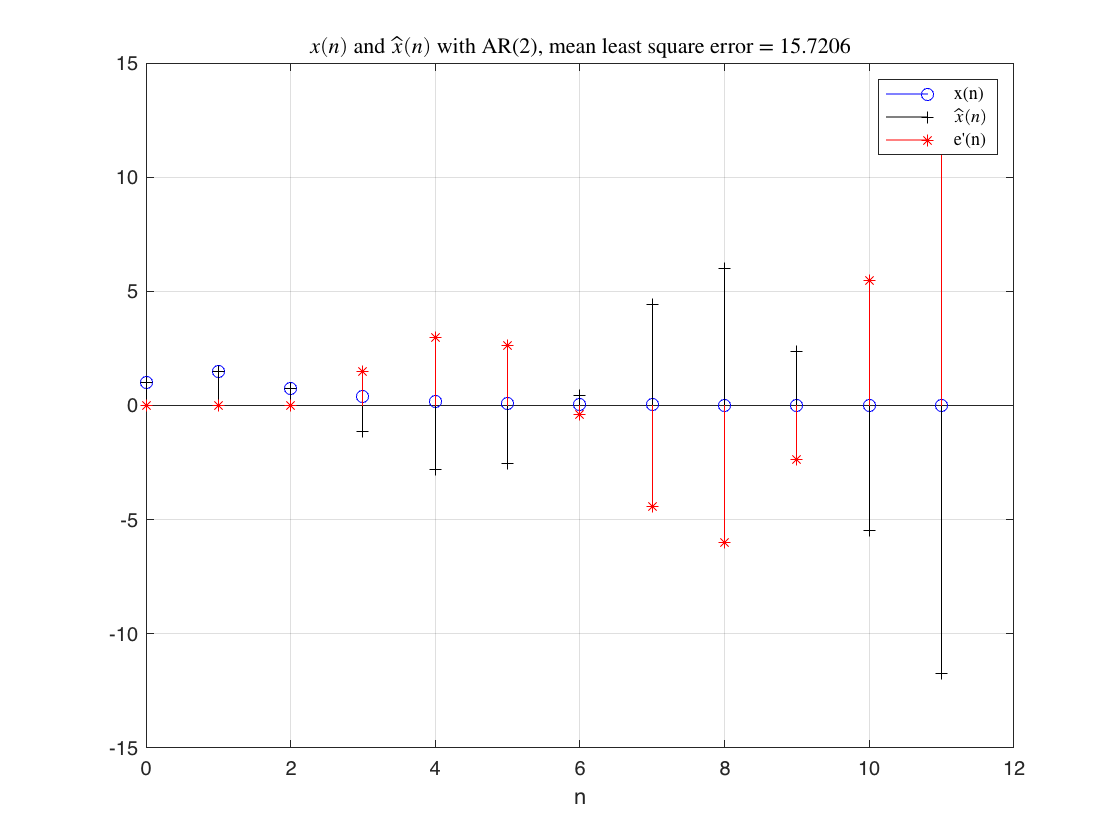

figure;
    stem(n, xn, 'bo');
    hold on;
    stem(n, xhat_ar, 'k+');
    stem(n, e_ar, 'r*');
    hold off;
    title(['$x(n)$ and $\hat{x}(n)$ with AR(2), mean least square error = ' num2str(Els_ar)] , 'Interpreter','latex');
    grid;
    xlabel('n');
    legend('x(n)', '$\hat{x}(n)$', 'e''(n)', 'Interpreter', 'latex');

Commentaire: Bien sur les 3 premiers échantillons, mais diverge ensuite

### b) Test with MA(2): p=0 and q=2


$$H(z) = b(0)+b(1)z^{-1}+b(2)z^{-2}$$


In this case the solution for $b_q(n)$ is obvious because $h(n)=b_q(n)$ so $b_q(n) = x(n)$ :

q = 2;
p = 0;
bq_ma = xn(1:q+1)

bq_ma =     1.0000
    1.5000
    0.7500


ap_ma = 1

ap_ma = 1

xhat_ma = impz(bq_ma, ap_ma, length(xn)); % impulse response
e_ma = xn-xhat_ma;
% Els_ma = sqrt(sum(e_ma.^2))
Els_ma = norm(e_ma)

Els_ma = 0.4330

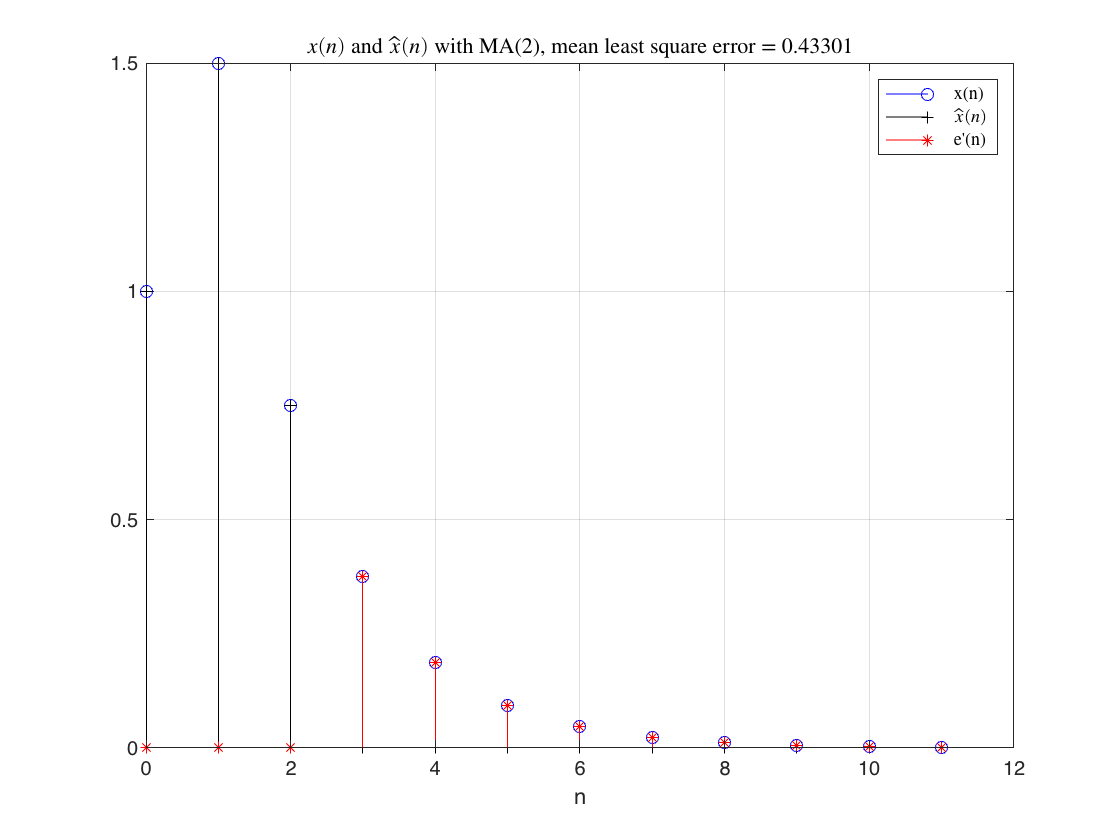

figure;
    stem(n, xn, 'bo');
    hold on;
    stem(n, xhat_ma, 'k+');
    stem(n, e_ma, 'r*');
    hold off;
    title(['$x(n)$ and $\hat{x}(n)$ with MA(2), mean least square error = ' num2str(Els_ma)] , 'Interpreter','latex');
    grid;
    xlabel('n');
    legend('x(n)', '$\hat{x}(n)$', 'e''(n)', 'Interpreter', 'latex');

> Parfait sur les 3 premiers échantillons, 0 ensuite.

### c) Test with ARMA(1,1): p=1 and q=1

In this case we need to solve with 2 step algorithm

**First **we compute the $a_p$ coeff as in point a)

q = 1;
p = 1;
Xq = X(q+2:q+p+1, 2:p+1)

Xq = 1.5000

Compute the vector $x_{q+1}$ as well:

xq_1 = X(q+2:q+p+1, 1)

xq_1 = 0.7500

if det(Xq)
    %ap_arma = inv(Xq)*(-xq_1); % pinv is used in case
    ap_arma = Xq\-xq_1;
    ap_arma = [1; ap_arma]
else
    disp('Xq is a singular matrix !')
end

ap_arma =     1.0000
   -0.5000


**Next** we compute the $b_q$ coefficients:

X0 = X(1:q+1, 1:p+1)

X0 =     1.0000         0
    1.5000    1.0000


bq_arma = X0*ap_arma

bq_arma =      1
     1


The transfer function $H(z)$ is

printsys(bq_arma', ap_arma', 'z')

 
num/den = 
 
    z + 1
   -------
   z - 0.5


xhat_arma = impz(bq_arma, ap_arma, length(xn));
e_arma = xn-xhat_arma;
Els_arma = sqrt(sum(e_arma.^2))

Els_arma = 0

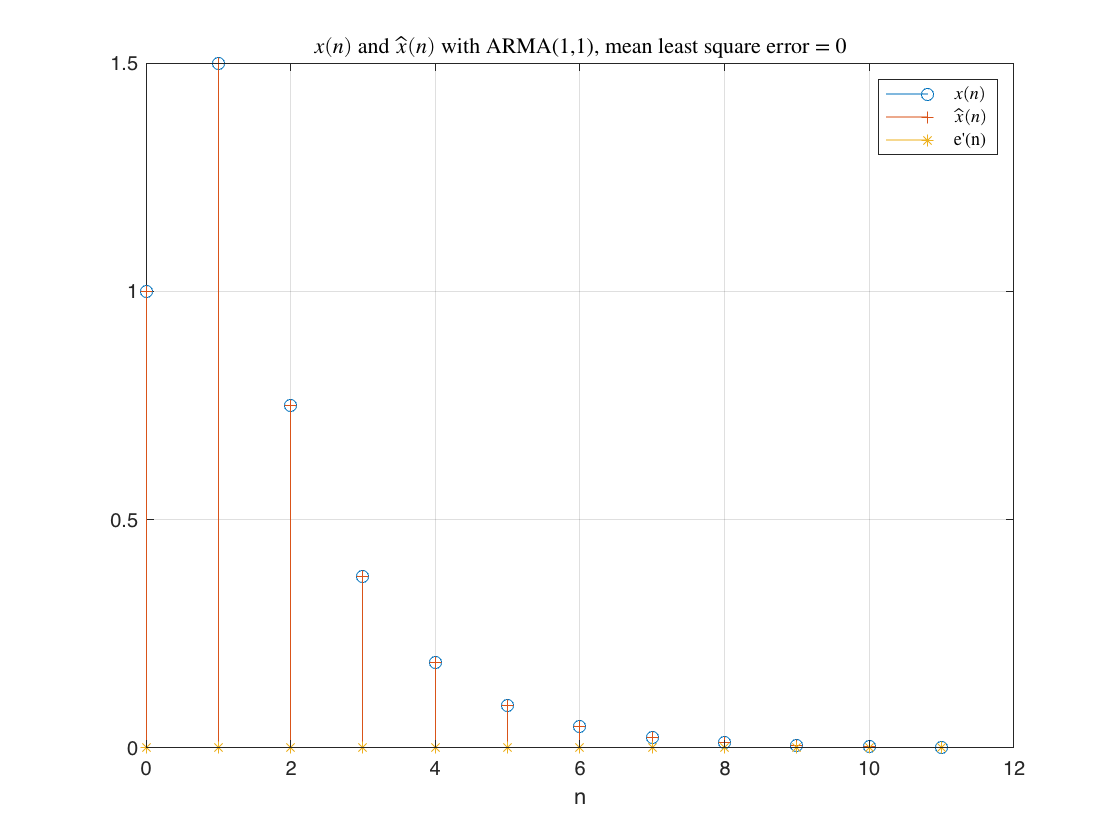

figure;
    stem(n, xn);
    hold on;
    stem(n, xhat_arma, '+');
    stem(n, e_arma, '*');
    hold off;
    title(['$x(n)$ and $\hat{x}(n)$ with ARMA(1,1), mean least square error = ' num2str(Els_arma)] , 'Interpreter','latex');
    grid;
    legend('$x(n)$', '$\hat{x}(n)$', 'e''(n)', 'interpreter', 'latex');
    xlabel('n');

### Creation myPade function and testing

p = 2;
q = 0;
[ap_test, bq_test, xhat_test, Els_test] = myPade(xn, p, q);
ap_test

ap_test =     1.0000
   -1.5000
    1.5000


bq_test

bq_test = 1

Els_test

Els_test = 15.7206

## Ex 4.3.3 : Singular example

Digital filter approximation

x2 = [1 4 2 1 3];
p = 2;
q = 2;

Compute the pade approximation with the pade function:

%[ap, bq, xhat, Els] = myPade(x2, p, q); % Error Xq is a singular matrix

The Xq matrix is singular in this case!

That means the assumption that $ap(0) = 1$ is incorrect for this model so we put it to 0.

## Ex 4.3.4 : Filter design using the Padé approximation

The problem of the filter approximation is to find the impulse response $h(n)$ of the filter from a frequency constraints. For this example, to be as simple as possible we want to synthetize a filter with a frequency response $|H(jf)| = 1$ for $f<F_p$ and 0 for $F_p<f<0.5$.

Additionaly we want a linear phase response then $H(jf) = e^{jn_d2\pi f}$ for $f<F_p$ and $0$ for $F_p<f<0.5$, the constant $n_d$ is the time delay of the filter to assure the causality of it.


$$H(jf) = \begin{cases}e^{jn_d2\pi f} \; ; |f| < 0.25 \\ 0 \qquad ; \text{otherwise}
\end{cases}$$
 

Since the frequency response is a rectangular function the inverse transform is a sinc function of the variable $n$, the impulse response is:


$$h(n) = \frac{\sin[(n-n_d)\pi/2]}{(n-n_d)\pi}$$
 

With the function sinc we write it as: $h_n = \frac{1}{2} \cdot \text{sinc}((n-n_d)\cdot 2 \cdot F_p)$

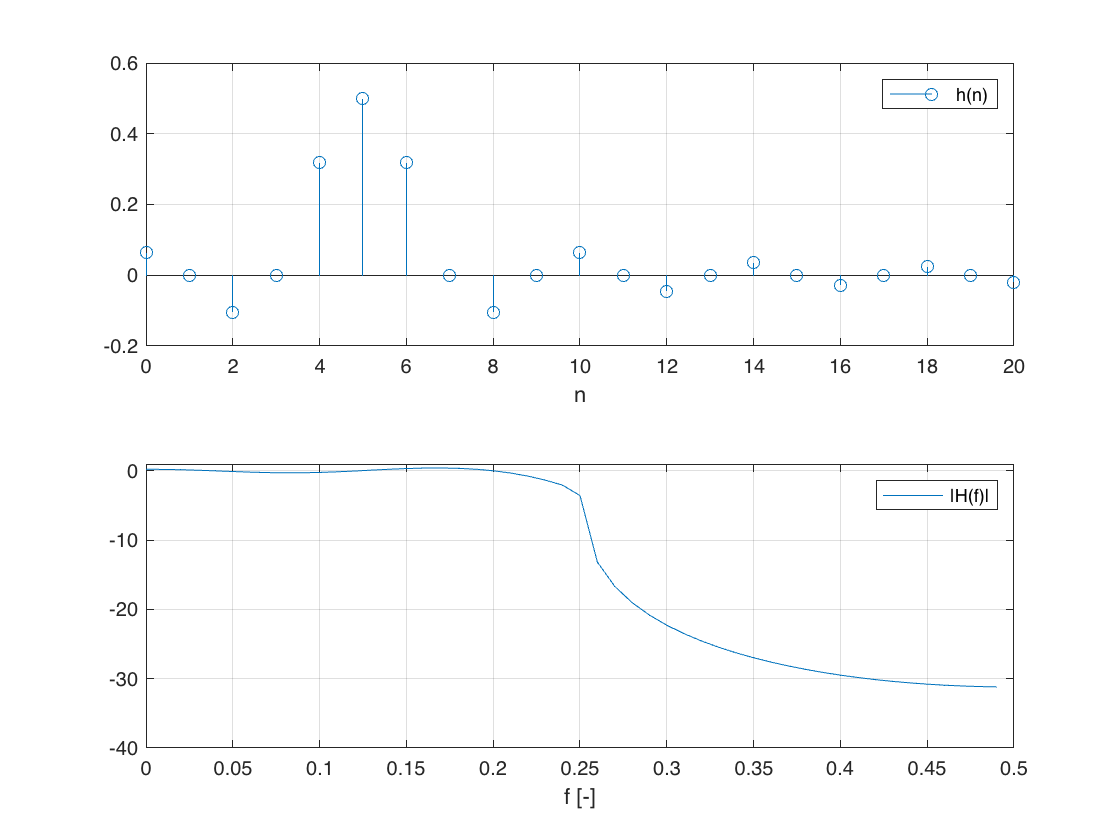

N = 100;
Fp = 0.25;
n = 0:N-1;
nd = 5;

hn = 1/2 * sinc((n-nd)*2*Fp);
H = fftshift(fft(hn));
f = -0.5:1/N:0.5-0.5/N;

figure;
tiledlayout(2,1);
nexttile;
    stem(n,hn);
    axis([0,20,-0.2,0.6]);
    grid;
    xlabel('n');
    legend('h(n)');
nexttile;
    plot(f, 20*log10(abs(H)));
    axis([0,0.5,-40,1]);
    grid;
    xlabel('f [-]');
    legend('|H(f)|');

If we design a FIR filter with $q=10$ and $p=0$ (MA) the Padé approximation will give the first 11 values of the $h(n)$. In this case $b_q(n) = h(n)$ for $n=0\dots 10$ 

p = 0;  % degree denominator (poles)
q = 10; % degree numerator (zeros)
[apFIR, bqFIR] = myPade(hn, p, q);

We could plot the frequency response of this filter with the function `freqz():`

tf_FIR = tf(bqFIR', [apFIR, zeros(1, length(bqFIR) - length(apFIR))], 1)

tf_FIR =
 
                                                                                                                
  0.06366 z^10 - 1.949e-17 z^9 - 0.1061 z^8 + 1.949e-17 z^7 + 0.3183 z^6 + 0.5 z^5 + 0.3183 z^4 + 1.949e-17 z^3 
                                                                                                                
                                                                          - 0.1061 z^2 - 1.949e-17 z + 0.06366  
                                                                                                                
  --------------------------------------------------------------------------------------------------------------
                                                           
                                                       z^10
                                                           
 
Sample time: 1 seconds
Discrete-time transfer function.



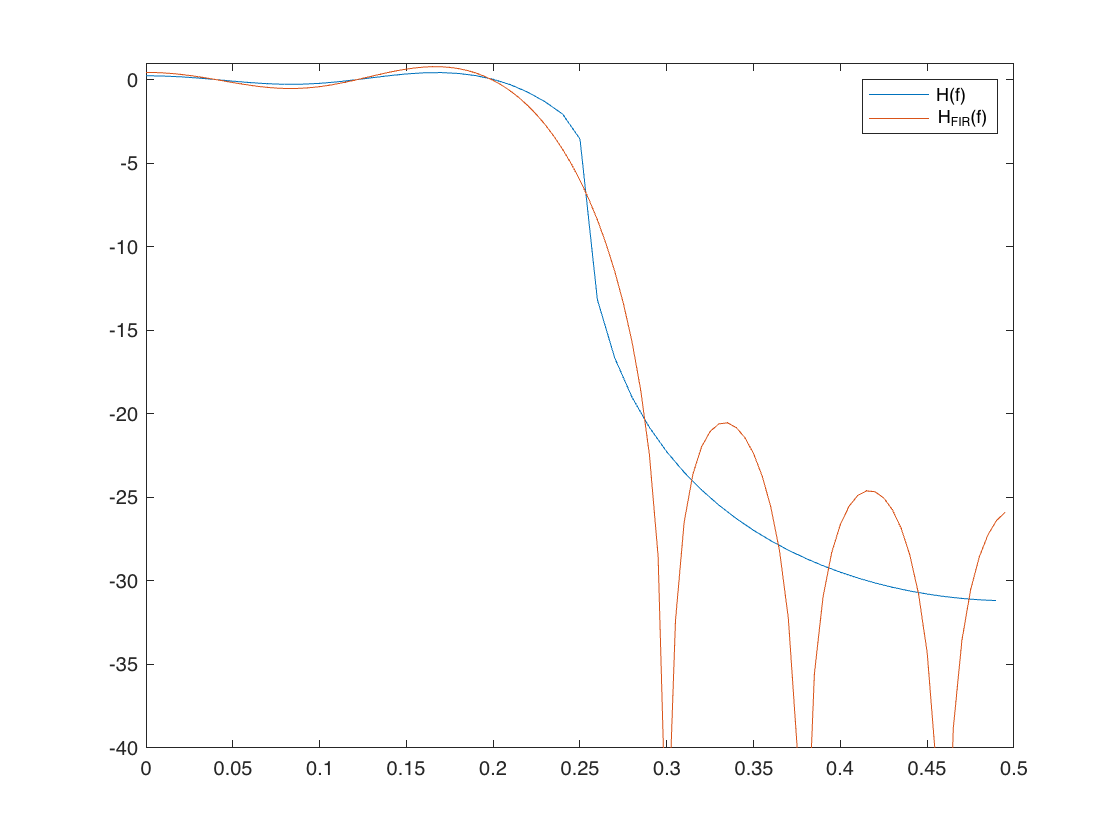

[H_FIR, f_FIR] = freqz(bqFIR, apFIR, N, 1);

figure;
    plot(f, 20*log10(abs(H)), ...
         f_FIR, 20*log10(abs(H_FIR)));
    legend('H(f)', 'H_{FIR}(f)');
    axis([0,0.5,-40,1]);

We want to find the transfer function of an ARMA system with $p=6$ and $q=6$:

p=6;
q=6;
[apIIR, bqIIR, ~, ElsIIR] = myPade(hn, p, q)

apIIR =     1.0000
   -2.5171
    3.9055
   -4.0872
    2.9647
   -1.4088
    0.3500


bqIIR =     0.0637
   -0.1602
    0.1425
    0.0069
    0.0927
    0.0428
    0.0106


ElsIIR = 0.1365

tf_IIR = tf(bqIIR', apIIR', 1)

tf_IIR =
 
  0.06366 z^6 - 0.1602 z^5 + 0.1425 z^4 + 0.006869 z^3 + 0.09267 z^2 + 0.04277 z + 0.01064
  ----------------------------------------------------------------------------------------
            z^6 - 2.517 z^5 + 3.905 z^4 - 4.087 z^3 + 2.965 z^2 - 1.409 z + 0.35
 
Sample time: 1 seconds
Discrete-time transfer function.



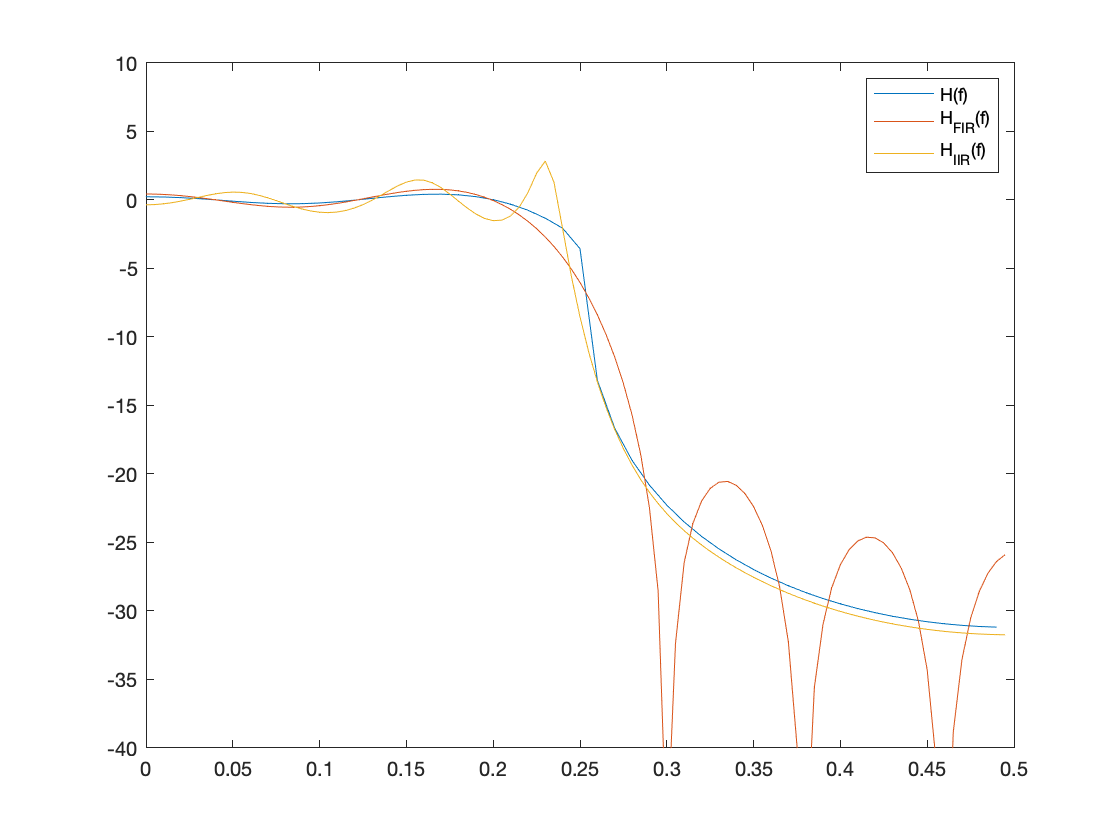

[H_IIR, f_IIR] = freqz(bqIIR, apIIR, N, 1);

figure;
    plot(f, 20*log10(abs(H)), ...
         f_FIR, 20*log10(abs(H_FIR)), ...
         f_IIR, 20*log10(abs(H_IIR)));
    legend('H(f)', 'H_{FIR}(f)', 'H_{IIR}(f)');
    axis([0,0.5,-40,10]);

Compute the impulse responseof this filter over the $N$ samples and compare to the original impulse response $h(n)$:

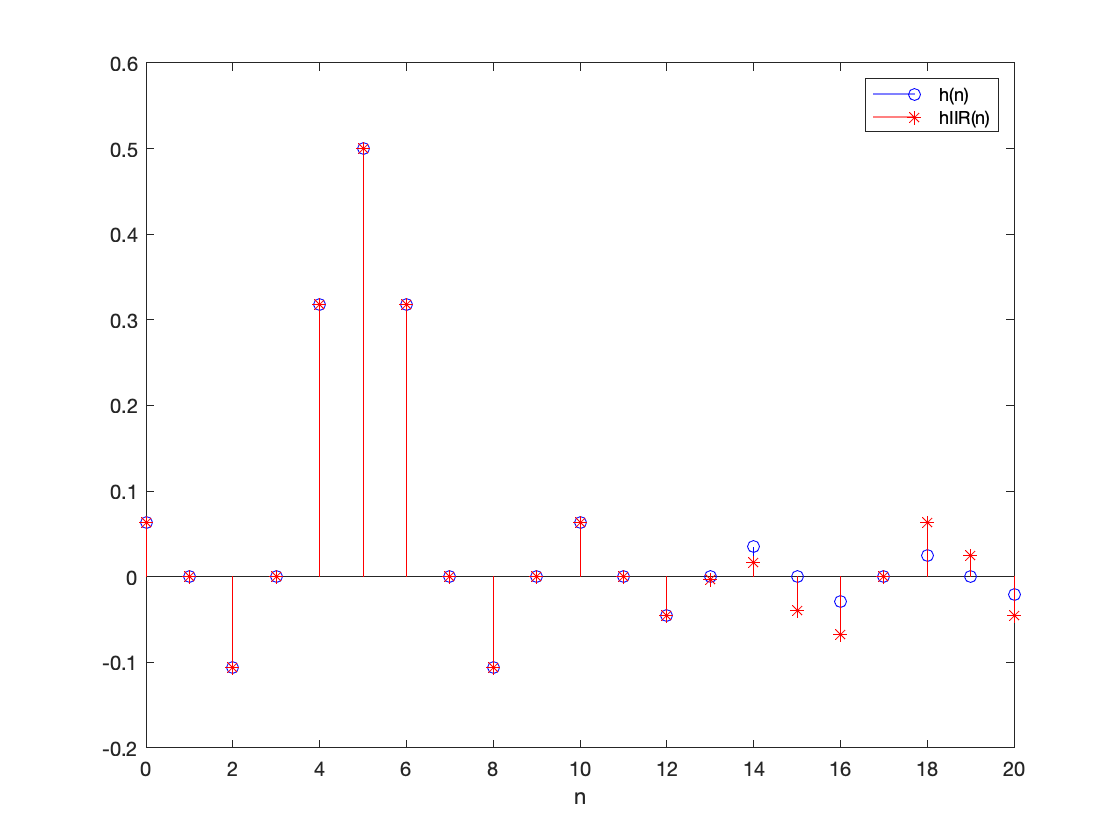

hiir = impz(bqIIR, apIIR, N);

figure;
    stem(n, hn, 'bo');
    hold on;
    stem(n, hiir, 'r*');
    xlabel('n');
    legend('h(n)', 'hIIR(n)');
    axis([0,20,-0.2,0.6]);